# State space example for Week 7 

define some values for capacitancem inductance and resitance

Cap = 1; L = 1; R = 1;

## Define state space model and label states inputs and outputs

A = [0 -1/Cap; 1/L -R/L];
B = [1/Cap; 0];
C = [1 0; 0 1; 1 -R; 0 R; 0 -1];
D = [0; 0; 0; 0; 1];
circ_ss = ss(A, B, C, D, ...
'statename',{'v31' 'i1'}, 'inputname', 'u', 'outputname', {'v31' 'i1' 'v32' 'v21' 'i2'});

## Show model

circ_ss


circ_ss =
 
  A = 
        v31   i1
   v31    0   -1
   i1     1   -1
 
  B = 
        u
   v31  1
   i1   0
 
  C = 
        v31   i1
   v31    1    0
   i1     0    1
   v32    1   -1
   v21    0    1
   i2     0   -1
 
  D = 
        u
   v31  0
   i1   0
   v32  0
   v21  0
   i2   1
 
Continuous-time state-space model.



## Plot a step response

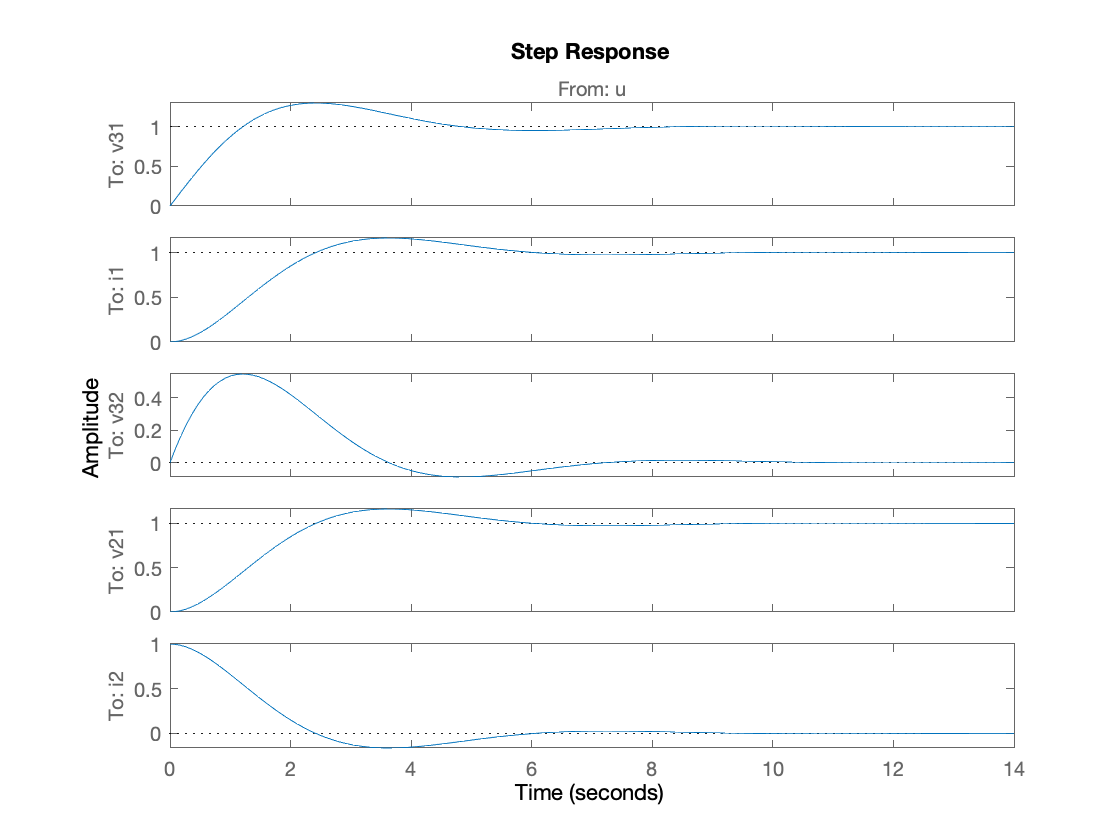

step(circ_ss)

## Convert to transfer function matrix

circ_tf=tf(circ_ss)


circ_tf =
 
  From input "u" to output...
            s + 1
   v31:  -----------
         s^2 + s + 1
 
             1
   i1:  -----------
        s^2 + s + 1
 
              s
   v32:  -----------
         s^2 + s + 1
 
              1
   v21:  -----------
         s^2 + s + 1
 
          s^2 + s
   i2:  -----------
        s^2 + s + 1
 
Continuous-time transfer function.



## Determine poles and zeros

circ_zpk=zpk(circ_ss)


circ_zpk =
 
  From input "u" to output...
             (s+1)
   v31:  -------------
         (s^2 + s + 1)
 
              1
   i1:  -------------
        (s^2 + s + 1)
 
               s
   v32:  -------------
         (s^2 + s + 1)
 
               1
   v21:  -------------
         (s^2 + s + 1)
 
           s (s+1)
   i2:  -------------
        (s^2 + s + 1)
 
Continuous-time zero/pole/gain model.



## The state transition matrix

Calculated using the symbolic math tools provided by MATLAB See help symbolic

syms phi t s
phi = inv(s*eye(2) - A)

$$phi = \left(\begin{array}{cc} \frac{s+1}{s^{2}+s+1} & -\frac{1}{s^{2}+s+1}\\ \frac{1}{s^{2}+s+1} & \frac{s}{s^{2}+s+1} \end{array}\right)$$

## The state transfer matrix

G = C*phi*B + D

$$G = \left(\begin{array}{c} \frac{s+1}{s^{2}+s+1}\\ \frac{1}{s^{2}+s+1}\\ \frac{s+1}{s^{2}+s+1}-\frac{1}{s^{2}+s+1}\\ \frac{1}{s^{2}+s+1}\\ 1-\frac{1}{s^{2}+s+1} \end{array}\right)$$

G = simplify(G)

$$G = \left(\begin{array}{c} \frac{s+1}{s^{2}+s+1}\\ \frac{1}{s^{2}+s+1}\\ \frac{s}{s^{2}+s+1}\\ \frac{1}{s^{2}+s+1}\\ 1-\frac{1}{s^{2}+s+1} \end{array}\right)$$

pretty(G)

/      s + 1     \
|   ----------   |
|    2           |
|   s  + s + 1   |
|                |
|        1       |
|   ----------   |
|    2           |
|   s  + s + 1   |
|                |
|        s       |
|   ----------   |
|    2           |
|   s  + s + 1   |
|                |
|        1       |
|   ----------   |
|    2           |
|   s  + s + 1   |
|                |
|          1     |
| 1 - ---------- |
|      2         |
\     s  + s + 1 /

